% Load all images from folder
imds = datastore("Images\calibrated\*.jpg");
imgs = readall(imds);

% Display text
disp("There are: " + length(imgs) + " images.")

% Write images back as another name
%imwrite(img01, "Images\calibrated\mars01.jpg")
%imwrite(img02, "Images\calibrated\mars02.jpg")
%imwrite(rover, 'Images\calibrated\rover.jpg');

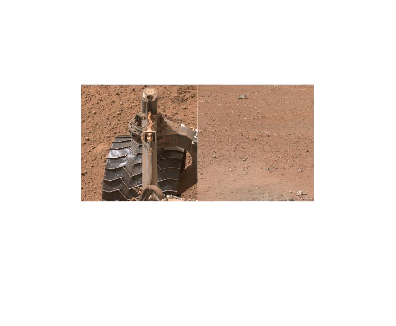

% Load rover and mars images
rover = imread('Images\calibrated\rover.jpg');
mars = imread('Images\calibrated\mars01.jpg');

% Show the pair
imshowpair(rover, mars, "montage")

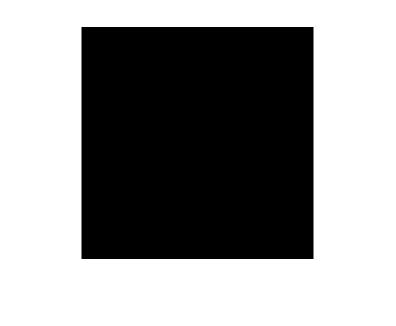

grayRover = rgb2gray(rover);
%filtRover = rescale(stdfilt(grayRover, true(15)));
roverRNG = rangefilt(grayRover, true(15));
imshow(roverRNG)

roverGray = rgb2gray(rover);
marsGray = rgb2gray(mars);

[l,a,b] = imsplit(rgb2lab(rover));
[ml,ma,mb] = imsplit(rgb2lab(mars));

roverBW = imbinarize(roverGray, "adaptive");
marsBW = imbinarize(marsGray, "adaptive");

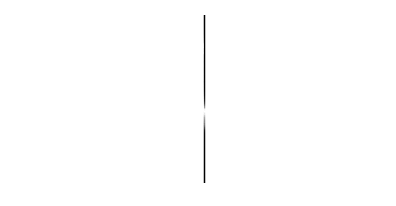

imhist(roverGray)

imhist(marsGray)

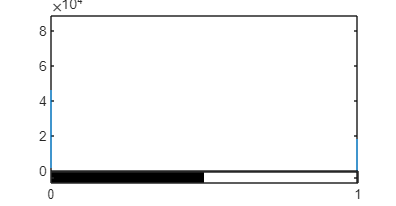

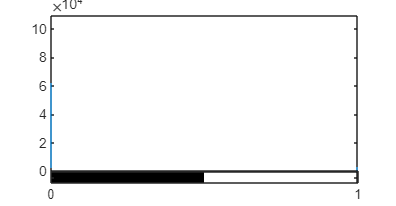

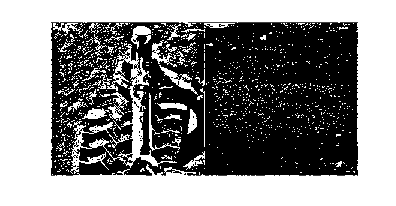

imshowpair(roverBW, marsBW, "montage")

img01 = imread("Images\calibrated\mars01.jpg");
img02 = imread("Images\calibrated\mars02.jpg");

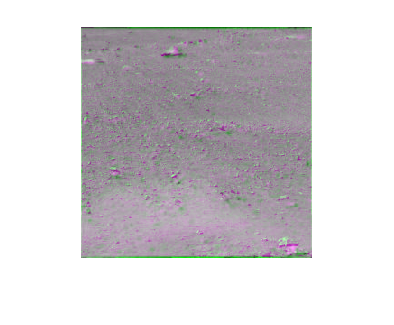

% Converting to double to perform calculations
marsDbl = im2double(img01);

% Convert to grayscale
marsGray1 = im2gray(img01);
marsGray2 = im2gray(img02);

% Display
imshowpair(marsGray1, marsGray2)

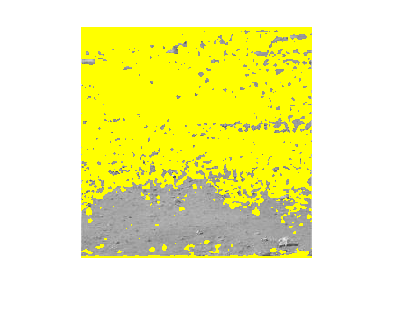

% Thresholding 
thresh_mg2 = imbinarize(marsGray2);
thresh_mg1 = imbinarize(marsGray2);

% Overlay
lay1 = imoverlay(marsGray1, ~thresh_mg1);
lay2 = imoverlay(marsGray2, thresh_mg2);

imshow(lay1)

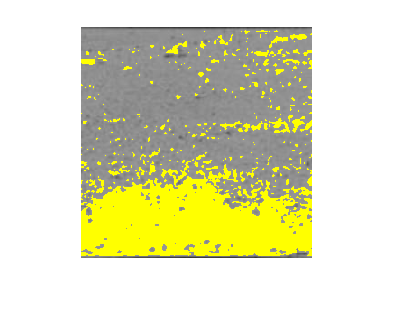

imshow(lay2)

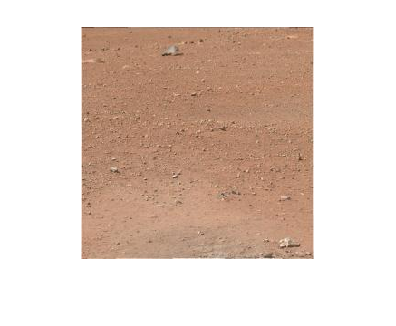

mars = imread("Images\calibrated\mars01.jpg");
imshow(mars)

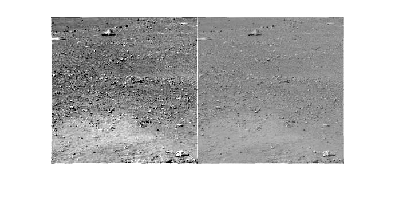

grayMars = im2gray(mars);
marsAdj = imadjust(grayMars);
imshowpair(marsAdj, grayMars, "montage")

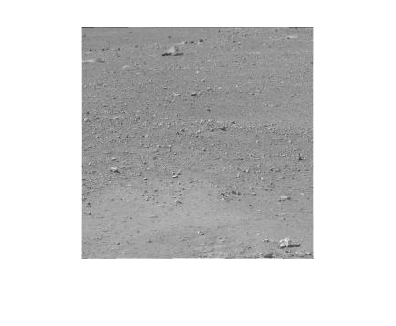

imshow(grayMars)

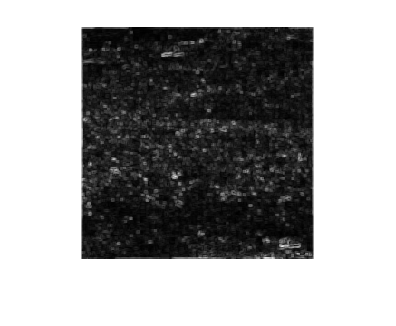

filtMars = rescale(stdfilt(grayMars));
imshow(filtMars)

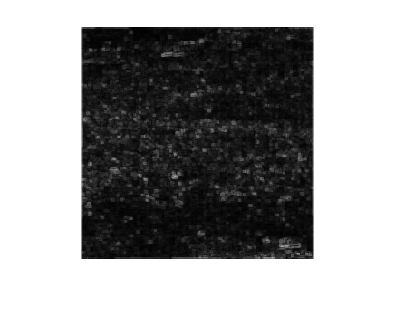

RNGMars = rangefilt(grayMars, true(3));
imshow(RNGMars)

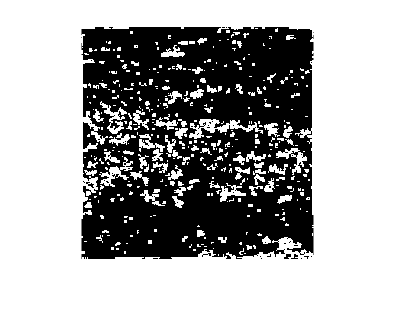

BWMars = imbinarize(RNGMars);
imshow(BWMars)

closeMars = imclose(BWMars, strel("disk",1));
cleanMars = imopen(closeMars, strel("disk", 1))

cleanMars = 256×256 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

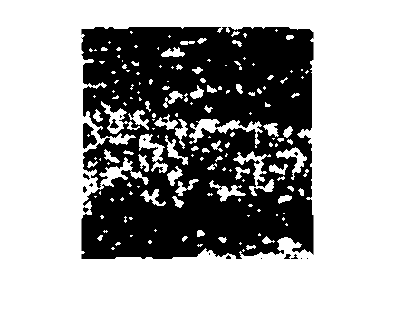

imshow(cleanMars)

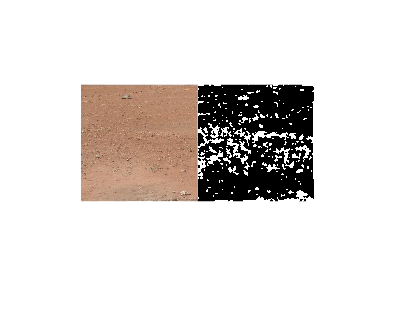

imshowpair(mars, cleanMars, "montage")

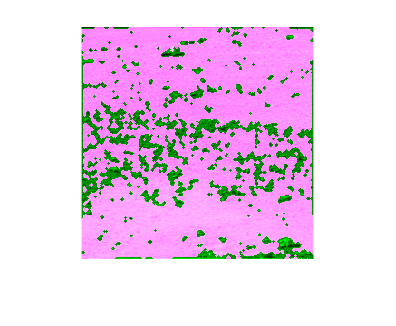

imshowpair(mars, ~cleanMars)